# 图像局部遮挡敏感性分析

在输入图像的不同区域，用不同尺寸的遮挡图块遮挡，分析遮挡不同部位，对ImageNet图像分类模型预测结果的影响。

通过图像局部遮挡敏感性分析，可以分析模型预测指定类别决策时，倚仗的关键区域。

MATLAB深度学习工具箱提供了内置的 `occlusionSensitivity` 函数，实现图像局部遮挡敏感性分析。

同济子豪兄可解释机器学习公开课

课程主页：https://github.com/TommyZihao/zihao_course/blob/main/XAI

参考教程：https://ww2.mathworks.cn/help/deeplearning/ug/understand-network-predictions-using-occlusion.html

参考教程：https://ww2.mathworks.cn/help/deeplearning/ref/occlusionsensitivity.html

2022-11-1

## 准备工作

输入 deepNetworkDesigner 打开深度网络设计器，安装 GoogLeNet 预训练图像分类模型。

% deepNetworkDesigner

## 载入GoogLeNet

net = googlenet;

## 查看神经网络结构

% analyzeNetwork(net);

## 获取输入图像尺寸和输出类别名称

inputSize = net.Layers(1).InputSize(1:2); % 获取模型输入图像尺寸
classes = net.Layers(end).Classes;        % 获取模型输出类别名称

## 载入测试图像

img = imread('cat_dog.jpg');
img = imresize(img, inputSize); % 缩放至模型要求的输入尺寸

## 输入图像分类模型预测，获取top-3类别

[YPred, scores] = classify(net, img);
[~,topIdx] = maxk(scores, 3);
topScores = scores(topIdx);
topClasses = classes(topIdx);

## 可视化图像分类预测结果

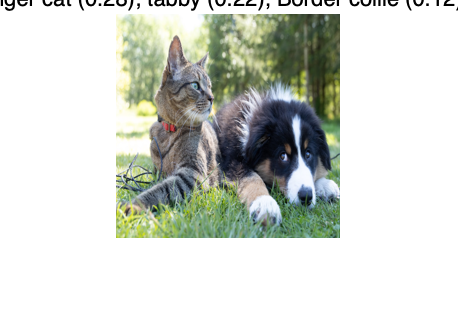

imshow(img)
titleString = compose("%s (%.2f)",topClasses,topScores');
title(sprintf(join(titleString, "; ")));

## “tiger cat”类别的局部遮挡敏感性分析图

map = occlusionSensitivity(net, img, YPred);

## 可视化

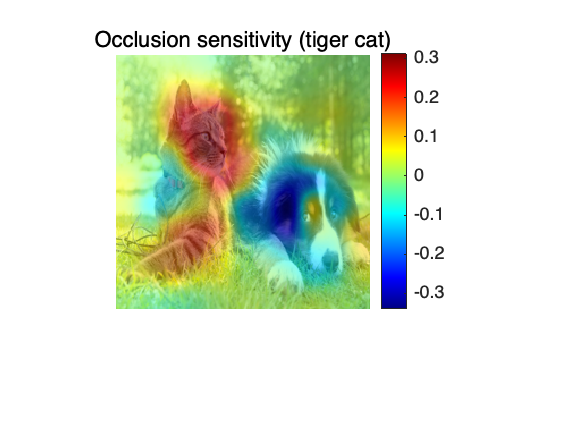

imshow(img, 'InitialMagnification', 150)
hold on
imagesc(map, 'AlphaData', 0.5)
colormap jet
colorbar

title(sprintf("Occlusion sensitivity (%s)", YPred))

红色区域，被遮挡后，会显著降低模型预测出“tiger cat”的概率。对应真实的“tiger cat”语义区域。

蓝色区域，被遮挡后，会显著提升模型预测出“tiger cat”的概率。对应其它干扰类别区域。

## “border collie”类别的局部遮挡敏感性分析图

secondClass = topClasses(3);
map = occlusionSensitivity(net, img, secondClass);

## 可视化

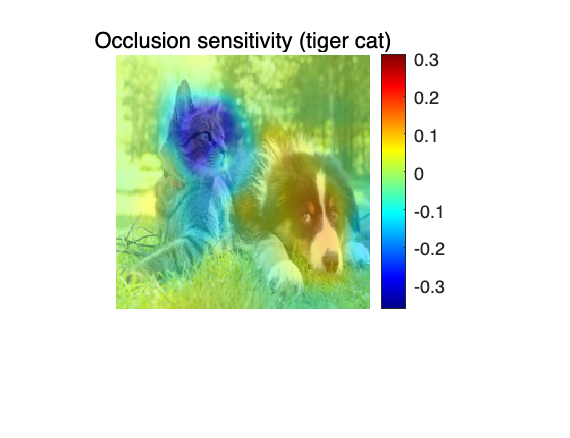

imshow(img, 'InitialMagnification', 150)
hold on
imagesc(map, 'AlphaData',0.5)
colormap jet
colorbar

title(sprintf("Occlusion sensitivity (%s)", YPred))

## 更改遮挡图块的尺寸和滑动步长

`Stride` ：遮挡滑块滑动步长，越小，热力图越细粒度。但需要消耗更长时间和内存。

`MaskSize ：遮挡滑块尺寸，越小，热力图越细粒度，但可能会带来噪声。`

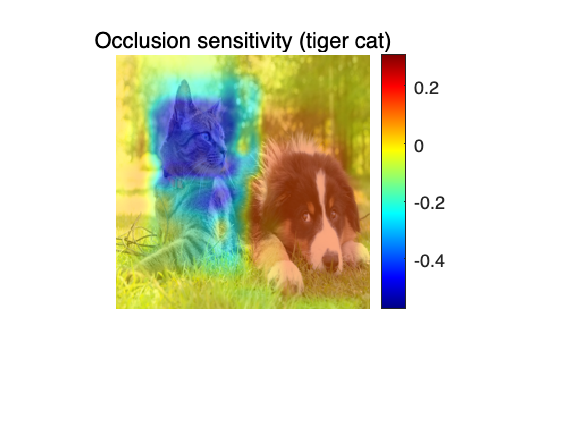

map = occlusionSensitivity(net, img, secondClass, 'Stride', 10, 'MaskSize', 80);
imshow(img, 'InitialMagnification', 150)
hold on
imagesc(map, 'AlphaData', 0.5)
colormap jet
colorbar

title(sprintf("Occlusion sensitivity (%s)", YPred))

## 绘制top-3每个类别的局部遮挡敏感性分析热力图

topClasses = classes(topIdx);
topClassesMap = occlusionSensitivity(net, img, topClasses, 'Stride', 10, 'MaskSize', 80);

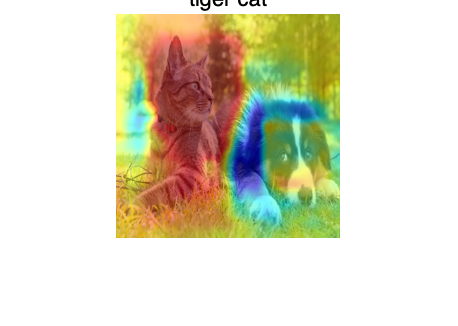

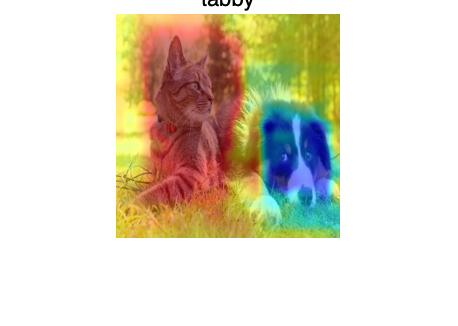

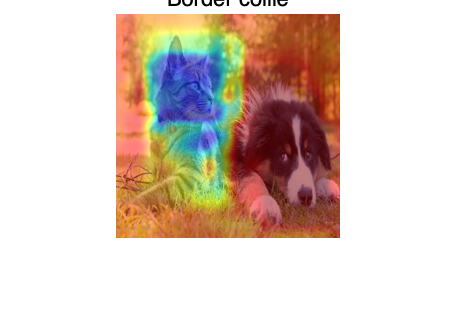

for i=1:length(topIdx)        
    figure
    imshow(img); 
    hold on
    imagesc(topClassesMap(:,:,i), 'AlphaData', 0.5);
    colormap jet;
    
    classLabel = string(classes(topIdx(i)));
    title(sprintf("%s", classLabel));
end